# Non linear behaviours and control of single tank systems 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript focusses on single tank systems, both their behaviour and their control, in the presence of both uncertainty and non-linearity.  Uncertainty could be due to parameterisation errors (areas of tanks and outlet pipes might be estimated incorrectly) and disturbances (unexpected inflows), as well as the more normal measurement noise. It is interesting to investigate how effectively a control law can work in the presence of all of these components. 

The basis of this resource are two simulink files ***non_linear_tank_system_control101.slx, non_linear_tank_system_fbk_control101.slx*** as these allow convenient modelling of all the non-linear and uncertain components. Take a copy in your own area if you want to edit these for further study. Code to run the simulation and define the settings is given in the sections below, but the easiest way to interact initially is through the app files: ***nonlinear_tank_behaviour_control101.mlapp***, ***nonlinear_tank_system_control.mlapp***.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox) 

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script, as shown below. This resource collects the core parameter values from the workspace and a step input component, runs the simulation and then the outputs are sent back to the workspace for plotting.

To modify the simulink diagrams and other details, make a copy into your own area first.

## Table of contents

- Simple Simple hydraulic system models

- Introducing feedback

- The app file (covers only the feedback scenario)

## 1. Simple hydraulic system models

### 1.1 Deviation variables

With linear systems, it is common to linearise around a given operating point and so that is what will be done here, although the simulink file will continue to use the full non-linear model. Deviations are usually taken relative to a steady-state, so for example (for states *x* and inputs *u*):


$$\hat{x} =x-x_{\textrm{ss}} ,\hat{u} =u-u_{\textrm{ss}}$$


Linearisation is often performed using a 1st order Taylor series.

### 1.1 A single tank

A tank system is taken to have a controllable flow into the tank, for example from the top, and an outflow that depends upon the depth. A schematic is given in Figure 1.1. 

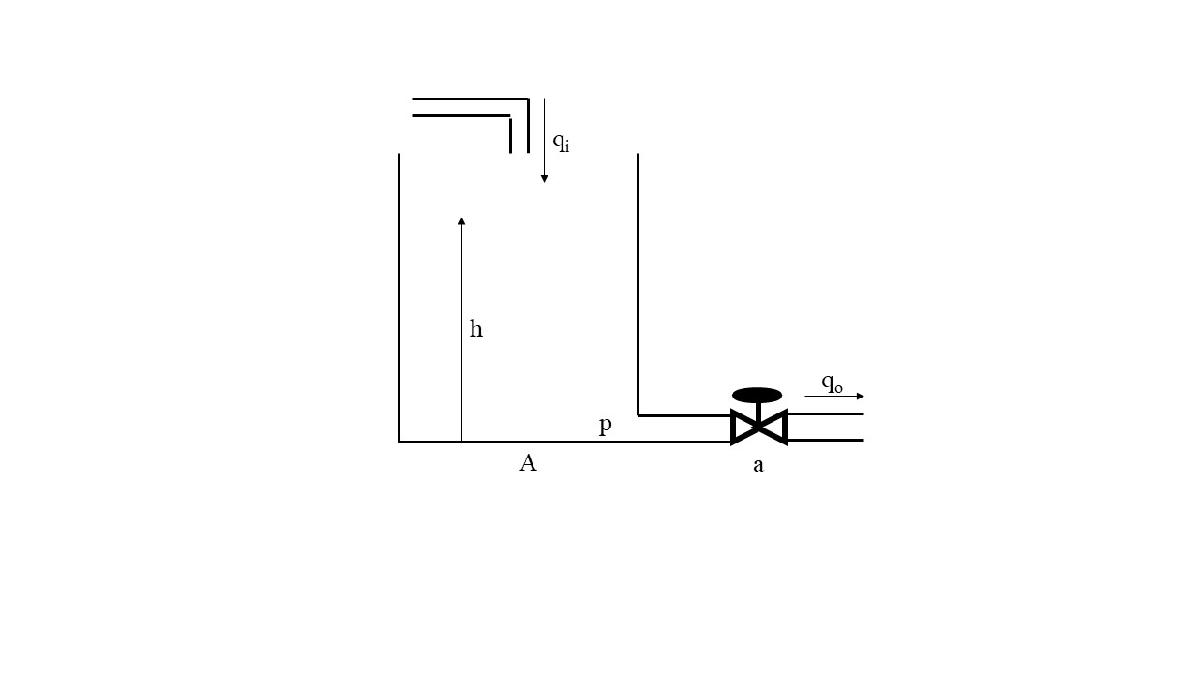

**Figure 1.1 **A single tank system

Let *P* be atmospheric pressure, *A* the cross-sectional area, *h* the  depth. The input flow depends upon an input signal u through a gain, that is:

$q_i =k_p u$ and the outlet flow depends upon the presssure ifference across the outlet pipe. Simple modelling equations are common in the textbooks, as follows:

$A\frac{d\;h}{\textrm{dt}}=q_i -q_o ;\;\;\;\;\;\;\;\;q_o =\frac{1}{R}\sqrt{\left(p-p_o \right)};\;\;\;\;\;\;\;\;\;\;\;\left(p-P\right)=\rho g\;h$;        $C=\frac{\rho g}{R\;A}$      (1)

Define the steady-state operating point as: $h_{\textrm{ss}} ,q_{\textrm{ss}} ,{\;\;\textrm{with}\;\;\;\;p}_{\textrm{ss}} =\rho g\;h_{\textrm{ss}} +P,{\;\;\;\;\;\;\;\;q}_{\textrm{ss}} =\frac{1}{R}\sqrt{\left(p_{\textrm{ss}} -p_o \right)}$

where *p* is the pressure at the bottom of the tank and $p_o$ the pressure at the end of the outflow,  *h* is the depth and *R* a constant that depends on the outflow pipe parameters. For convenience here, assume that: $P=p_o \ldotp$ Hence the model becomes:

$A\frac{d\;h}{\textrm{dt}}=q_i -\frac{1}{R}\sqrt{\rho \;g\;h}$  or  $\frac{d\;h}{\textrm{dt}}=\frac{1}{A}\left\lbrack q_i -\left(\frac{\sqrt{\rho g}}{R}\right)\sqrt{\;h}\right\rbrack$

Next express the non-linear term as a Taylor series around the steady-state: $\left(p_{\textrm{ss}} -P\right)=\rho g\;h_{\textrm{ss}}$, $q_{\textrm{ss}=} \frac{1}{R}\sqrt{\rho \;g\;h_{\textrm{ss}} }$. Hence:


$$\frac{1}{R}\sqrt{\rho \;g\;h}\approx \frac{1}{R}\left(\sqrt{\rho \;g\;h_{\textrm{ss}} }+\left\lbrack h-h_{\textrm{ss}} \right\rbrack \frac{\sqrt{\rho g}}{2\sqrt{h_{\textrm{ss}} }}\right)$$


Substitute this into the orginal model (1) and rewrite in terms of deviation variables. The linearised model is given as:

$A\frac{d\;\hat{h} }{\textrm{dt}}=\hat{q} +q_{\textrm{ss}} -\frac{1}{R}\left(\sqrt{\rho \;g\;h_{\textrm{ss}} }+\hat{h} \frac{\sqrt{\rho g}}{2\sqrt{h_{\textrm{ss}} }}\right)=\hat{q} -\hat{h} \left(\frac{\sqrt{\rho \;g}}{2R\sqrt{h_{\textrm{ss}} }}\right)=\hat{q} -\hat{h} C_l ;\;{\;\;\;\;\;\;\;\;\;\;C}_l =\left(\frac{\sqrt{\rho \;g}}{2R\sqrt{h_{\textrm{ss}} }}\right)$                  (2)

In transfer function format one can write:


$$\hat{H} \left(s\right)=\frac{1}{A\;s+C_l }\hat{Q} \left(s\right)=G\left(s\right)\hat{Q} \left(s\right);\;\;\;\;\;\;\;\;G\left(s\right)=\frac{1}{A\;\;s+C_l }$$


### 1.2 Simulation of a single tank model: linear and non-linear

A simulink file is created to capture both the non-linear (top blocks) and linear (lower blocks) model above (eqns. (1,2)); Figure 1.2 shows the simulink diagram. The code below shows which data needs to be defined in order to run the simulation; it should be self evident therefore how to make changes in order to perform individual investigations.

It will be clear immediately that the non-linear model behaves differently as soon as one moves away from the linearisation point and obviously, any blockage causes a huge difference compared to the orginal linear model. The linear model uses deviation variables relative to the linearisation point.

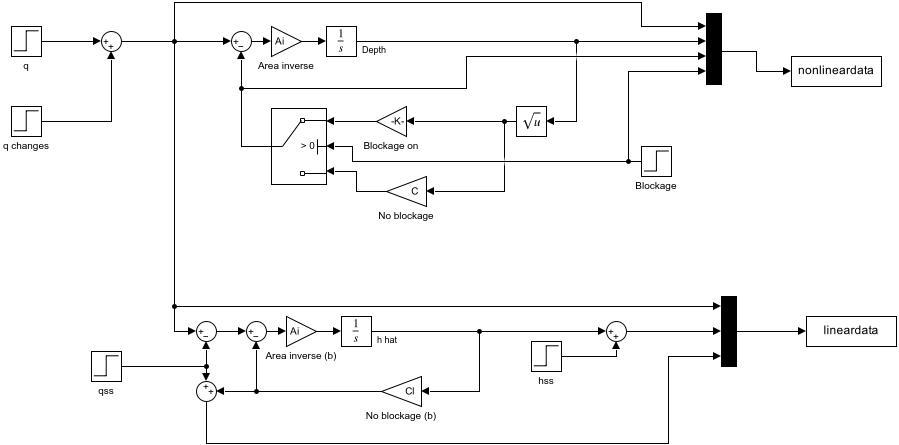

**Figure 1.2 **Screen capture of the simulink file ***non_linear_tank_system_control101.slx***

disp('*****************************')

*****************************


disp('Section 1.2 illustrations below')

Section 1.2 illustrations below



% to open simulink file and view the scope
%open non_linear_tank_system_control101.slx  

% Simulation parameters
blocksize = 0.2;  % size of blockage as percentage
qstep = 0.01;     % change in inflow compared to steady-state
endtime=2400;     % simulation run time
blockagetime=600; % time that blockage introduced
qchangetime = 1200; % time that change in flow introduced


% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
A=2;  Ai=1/A;  % tank area
Ae = A;  Aie = 1/Ae;  % estimated tank area
R=10^4;      % constant needed to determine outflow
Re = R;  % estimated R


C=sqrt(rho*g)/R;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
hss = 0.5;
qss = C*sqrt(hss);
% Linear model
Ce=sqrt(rho*g)/Re;
hsse = 0.5;
qsse = Ce*sqrt(hsse);
Cl=Ce/(2*sqrt(hsse));


% Simulation - results will appear in the scope
sim("non_linear_tank_system_control101_2023.slx");

Model 'non_linear_tank_system_control101_2023' was exported from R2024a to R2023b. To find blocks that were removed during the export operation, click here. Save the model to remove this notification.


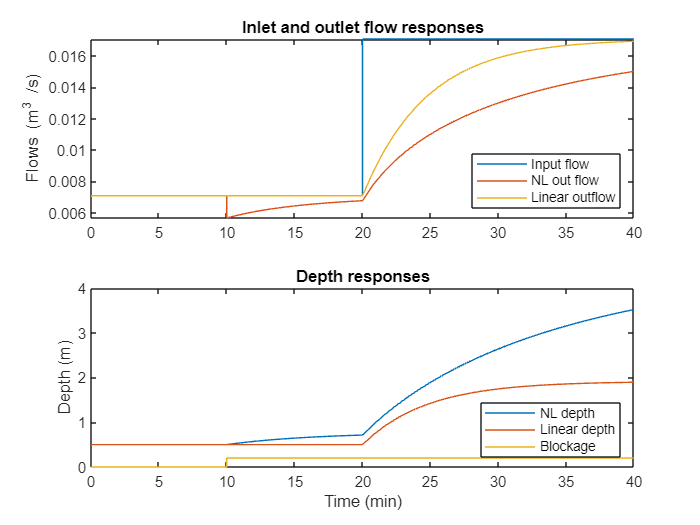

tt=nonlineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 1.3
yl = lineardata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
subplot(211)
plot(tout/60,[yy(:,[1,3]),yl(:,[3])]);
legend('Input flow','NL out flow','Linear outflow','Location','southeast')
title('Inlet and outlet flow responses')
ylabel('Flows (m^3 /s)')
subplot(212)
plot(tout/60,[yy(:,[2]),yl(:,2),yy(:,4)*blocksize]);
legend('NL depth','Linear depth','Blockage','Location','southeast')
ylabel('Depth (m)')
xlabel('Time (min)')
title('Depth responses')


%print(['-snon_linear_tank_system_control101'],'-djpeg',['non_linear_tank_system_control101b.jpg'])

### 1.3 The impact of parameterisation errors

It is interesting to study the impact of parameterisation errors on the accuracy of the linearised model, so for example:

- What if the area is estimated incorrectly (for example due to build up of scale or other contaminants)?

- Mis-estimation of the out flow pipe characteristics is implicitly equivalent to the presence of blockages discussed in the previous section.

The code below uses the estimated parameters for the linear model, but actual parameters in the non-linear model. Small differences will be seen in the initial steady-state part of the figures, but thereafter it is likely the nonlinear affects are more important.

disp('*****************************')

*****************************


disp('Section 1.3 illustrations below')

Section 1.3 illustrations below


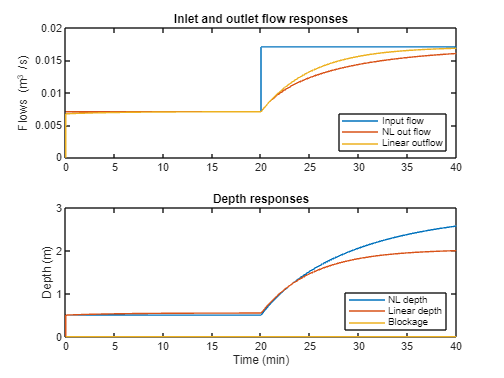


% Simulation parameters
blocksize = 0.0;  % size of blockage as percentage
qstep = 0.01;     % change in inflow compared to steady-state
endtime=2400;     % simulation run time
blockagetime=600; % time that blockage introduced
qchangetime = 1200; % time that change in flow introduced

% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
A=2;  Ai=1/A;  % tank area true
Ae = 2.1;  Aie = 1/Ae;  % estimated tank area
R=10^4;      % constant needed to determine outflow
Re = 1.05*10^4;  % estimated R

C=sqrt(rho*g)/R;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
hss = 0.5;
qss = C*sqrt(hss);
% Linear model
Ce=sqrt(rho*g)/Re;
hsse = 0.5;
qsse = Ce*sqrt(hsse);
Cl=Ce/(2*sqrt(hsse));


% Simulation - results will appear in the scope
sim("non_linear_tank_system_control101_2023.slx");
tt=nonlineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 1.3
yl = lineardata.signals.values; % stored in order as shown in Figure 1.3

% Plotting
subplot(211)
plot(tout/60,[yy(:,[1,3]),yl(:,[3])]);
legend('Input flow','NL out flow','Linear outflow','Location','southeast')
title('Inlet and outlet flow responses')
ylabel('Flows (m^3 /s)')
subplot(212)
plot(tout/60,[yy(:,[2]),yl(:,2),yy(:,4)*blocksize]);
legend('NL depth','Linear depth','Blockage','Location','southeast')
ylabel('Depth (m)')
xlabel('Time (min)')
title('Depth responses')

## 2 Introducing feedback

Ultimately we would like to control the depth in the tank, not withstanding the uncertainty. This resource will use simple PI compensation as derivative is not usually needed for 1st order systems. The focus will be on real issues that can impact on the behaviour, for example:

- What happens when the in-flow is constrained?

- What happens when depth measurement is noisy?

- What happens with temporary blockages.

- What happens with temporary disturbance in flows?

Using simulink means that these issues can be absorbed neatly and cleanly.

### 2.1. Nominal PI design

The design of the PI compensator is done using the linearised model, but thereafter the non-linear model is used for performance evaluation.  Consider a steady-state depth of $h_{\textrm{ss}} \;$as the notional point. The linearised model is given as:

 $\hat{H} \left(s\right)=\frac{1}{A\;s+C_l }\hat{Q} \left(s\right)=G\left(s\right)\hat{Q} \left(s\right);\;\;\;\;\;\;\;\;G\left(s\right)=\frac{1}{A\;\;s+C_l }$;   ${\;\;\;\;\;\;\;\;\;\;C}_l =\left(\frac{\sqrt{\rho \;g}}{2R\sqrt{h_{\textrm{ss}} }}\right)$

Conseequently, a simple heuristic PI design (see [https://controleducation.sites.sheffield.ac.uk/chapterfeedbackintro/sectionfbkpid)](https://controleducation.sites.sheffield.ac.uk/chapterfeedbackintro/sectionfbkpid)) is given as:


$$M\left(s\right)=K_p +\frac{K_i }{s};\;K_p =C_l ;\;K_i =\frac{C_l^2 }{A}$$


The expected responses can be determined using very simple code.

disp('*****************************')

*****************************


disp('Section 2.1 illustrations below')

Section 2.1 illustrations below


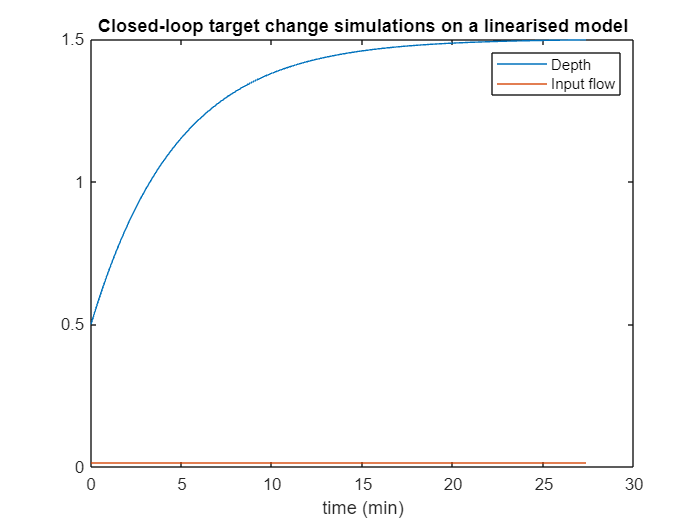

rho=1000; g=10;R=10^4; A=2;
C=sqrt(rho*g)/R;
Initial_target = 0.5;
qss = C*sqrt(Initial_target);
Cl=C/(2*sqrt(Initial_target));
G=tf(1,[A,Cl]);
Kp = Cl;
Ki = Cl^2/A;
M=tf([Kp,Ki],[1 0]);
[y,t]=step(feedback(G*M,1));
u=step(feedback(M,G),t);
subplot(111)
plot(t/60,y+Initial_target,t/60,u+qss)
legend('Depth','Input flow')
xlabel('time (min)')
title('Closed-loop target change simulations on a linearised model')

**Remark**: When initialising at a non-zero steady-state, one should also initialise the integral term at the expected steady-state input $q_{\textrm{ss}}$.

### 2.2 The simulation environment

Next it is necessary to define a simulink model containing all the real issues that might be expected. This is given in Figure 2 below where the non-linear model is in yellow and the measurement noise,   input saturation, disturbance in-flow  and blockages should be evident.

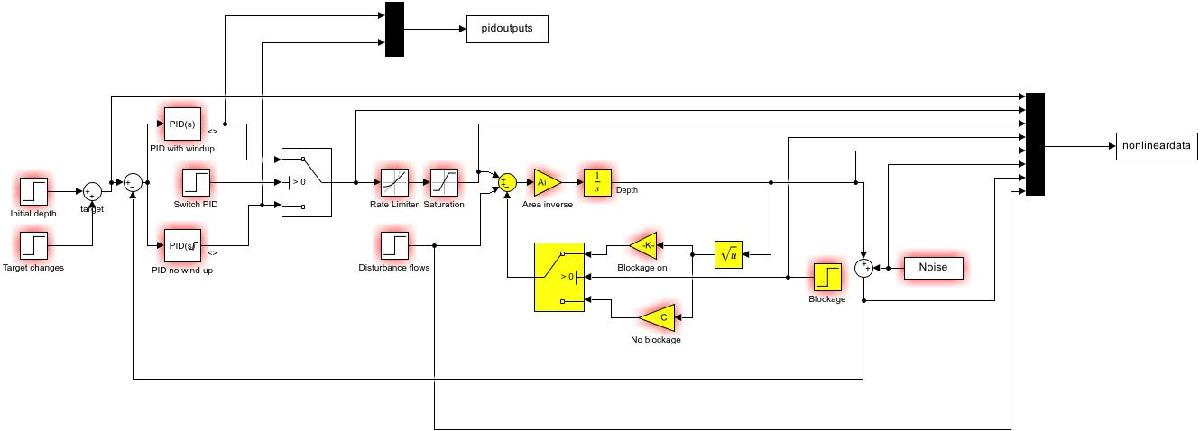

**Figure 2**. Simulink diagram of closed-loop control of a non-linear tank system (***non_linear_tank_system_fbk_control101.slx***)

The reader can set the timing and magnitude of the desired uncertain affects through a simple code snippet, as illustrated next, and thus carry out systematic investigations. Again, the estimated tank area and outlet pipe characteristics may differ from the true one, although here the estimated values are used only for the PI design as given in section 2.1.

- Change umax, Dumax and Dumin to observe impact of input limits on behaviour. Note that if umax is too small, integral saturation will occur if the control coding does not recognise and correct for this. 

- The impact of measurement noise is transparent in the output curves.

- The closed-loop rejects blockages, as long as there is sufficient control freedom to do so.

- The closed-loop will reject disturbance in-flows, if there is sufficient freedom to do so.

- Anti-windup is an option as users may to want to investigate this concept. **Open the PID block to explore some anti-wind up options **

disp('*****************************')

*****************************


disp('Section 2.2 illustrations below')

Section 2.2 illustrations below


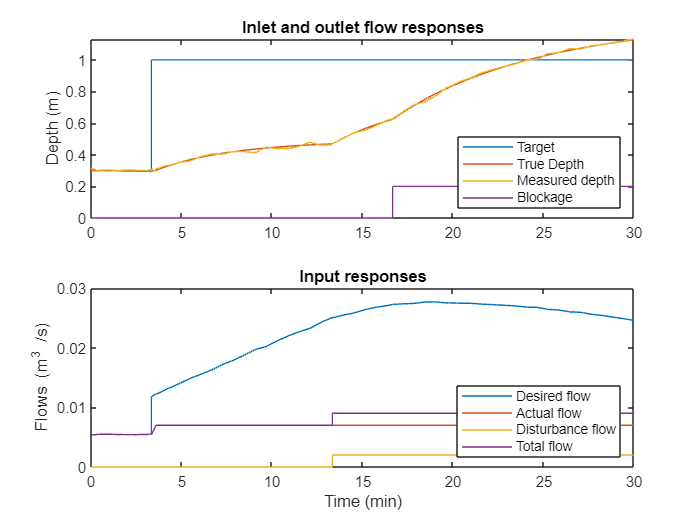

% open non_linear_tank_system_fbk_control101.slx
%print(['-snon_linear_tank_system_fbk_control101'],'-djpeg',['non_linear_tank_system_fbk_control101.jpg'])

% Simulation parameters
Initial_target = 0.3;
Targetchange = 0.7;
Targetchangetime = 200;
blocksize = 0.2;  % size of blockage as percentage
blockagetime=1000; % time that blockage introduced
endtime=1800;     % simulation run time
Noise=[];
Noise(:,1) = [0:endtime]';
Noise(:,2)=randn(1,endtime+1)'/100;    % magnitude of measurement noise
disturbanceflowtime=800;
disturbanceflow=0.002;
switchpidtime=0;   % With or without anti-windup
switchpid=1;       % no anti windup

% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
A=2;  Ai=1/A;  % tank area true
Ae = A; %2.1; % estimated tank area 
Aie = 1/Ae;  
R=10^4;      % constant needed to determine outflow
Re = R; %  1.05*10^4;  % estimated R
C=sqrt(rho*g)/R;
Ce=sqrt(rho*g)/Re;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
Dumax = 0.0001;    % rate limits on input
Dumin = -0.0001;
umax = 0.007;      % absolute limits on the input
umin = 0;
qss = Ce*sqrt(Initial_target);
Cl=Ce/(2*sqrt(Initial_target));

% PI compensator
Kp = Cl;
Ki = Cl^2/A;

% Simulation - results will appear in the scope
sim("non_linear_tank_system_fbk_control101_2023.slx");
tt=nonlineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 2


% Plotting
subplot(211)
plot(tt/60,[yy(:,[1,5,7]),yy(:,4)*blocksize]);
legend('Target','True Depth','Measured depth','Blockage','Location','southeast')
title('Inlet and outlet flow responses')
ylabel('Depth (m)')
%yy(:,7)*blocksize

subplot(212)
plot(tt/60,[yy(:,[2:3,8]),yy(:,3)+yy(:,8)]);
legend('Desired flow','Actual flow','Disturbance flow','Total flow','Location','southeast')
ylabel('Flows (m^3 /s)')
xlabel('Time (min)')
title('Input responses')

### 2.3 Anti-windup

The difference between the outputs fo the PID block with no anti-windup and one with anti-windup is shown here. The closed-loop simulation will use one or the other depending on the parameters set.

figure
disp('Section 2.3 illustrations below')

Section 2.3 illustrations below


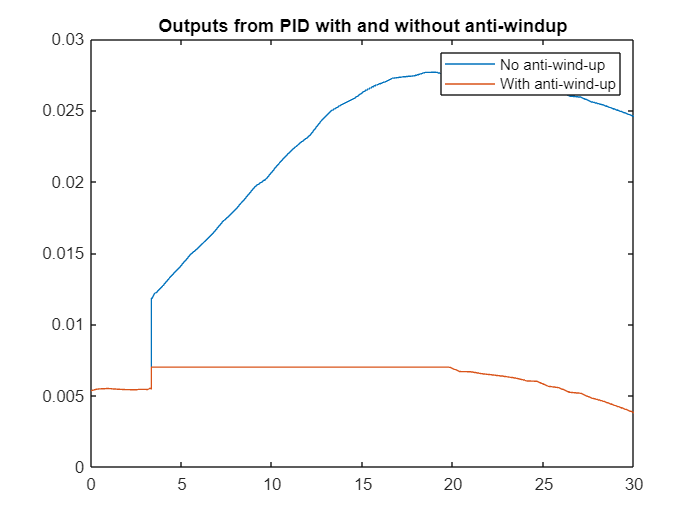

ww = pidoutputs.signals.values; % stored in order as shown in Figure 2
plot(tt/60,ww)
title('Outputs from PID with and without anti-windup')
legend('No anti-wind-up','With anti-wind-up')

### 2.4 Illustration of systematic investigations

It is straightforward to run the file above with a number of different settings and produce overlay plots to investigate different effects. This is illustrated here concisely, but left to the reader to take further. Assume section 2.2 above has already been run so that most data is already defined.

disp('Section 2.4 illustrations below')

Section 2.4 illustrations below


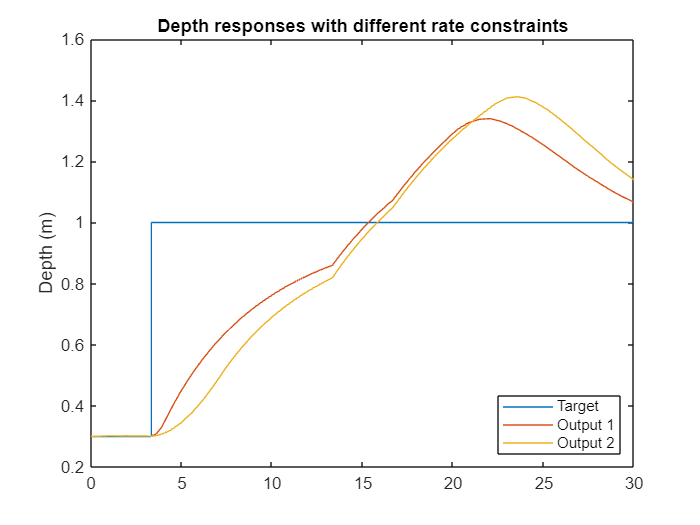


% Simulation 1
Dumax = 0.0001;    % rate limits on input
Dumin = -0.0001;
sim("non_linear_tank_system_fbk_control101_2023.slx");
tt1=nonlineardata.time;
yy1 = nonlineardata.signals.values; % stored in order as shown in Figure 2

% Simulation 2
Dumax = 0.00002;    % rate limits on input
Dumin = -0.00002;
sim("non_linear_tank_system_fbk_control101_2023.slx");
tt2=nonlineardata.time;
yy2 = nonlineardata.signals.values; % stored in order as shown in Figure 2

% Plotting
plot(tt1/60,yy1(:,[1,5]),tt2/60,yy2(:,5));
legend('Target','Output 1','Output 2','Location','southeast')
title('Depth responses with different rate constraints')
ylabel('Depth (m)')

## 3. The app files

While it is possible to interact with the simulation environment using code snippets, as above, it is far more convenient to use an app interface.  Albeit this may limit what the user can change, it is a lot easier and quicker to perform compare and contrast simulations looking at the impact of different aspects. Consequently, two app interfaces have been constructed and is summarised below.

***nonlinear_tank_behaviour_control101.mlapp, nonlinear_tank_control_control101.mlapp***

### ***3.1 App investigating open-loop behaviours of a non-linear tank model, subject to some uncertainty***

This app builds on section 1 above. A core point is to decide what factors a user might wish to change. The app allows the following changes, although only to  a relatively limited degree of precision:

- The magnitude of disturbance in-flow changes but not the timing (can be changed in source file data definitions).

- The magnitude of blockage changes but not the timing (can be changed in source file data definitions).

- Tank and outlet dimensions (area and outlet resistance); the value in the resistance slider is scaled by 1000.

- The linearisation point is based on the initial depth which may not be consistent with the initial inlet flow.

- The buttons are used to switch the disturbance effects on and off (green means on).

Users will quickly be able to explore the differences in behaviour between the linear and non-linear models and thus discern the extent to which a linearised model might be useful.

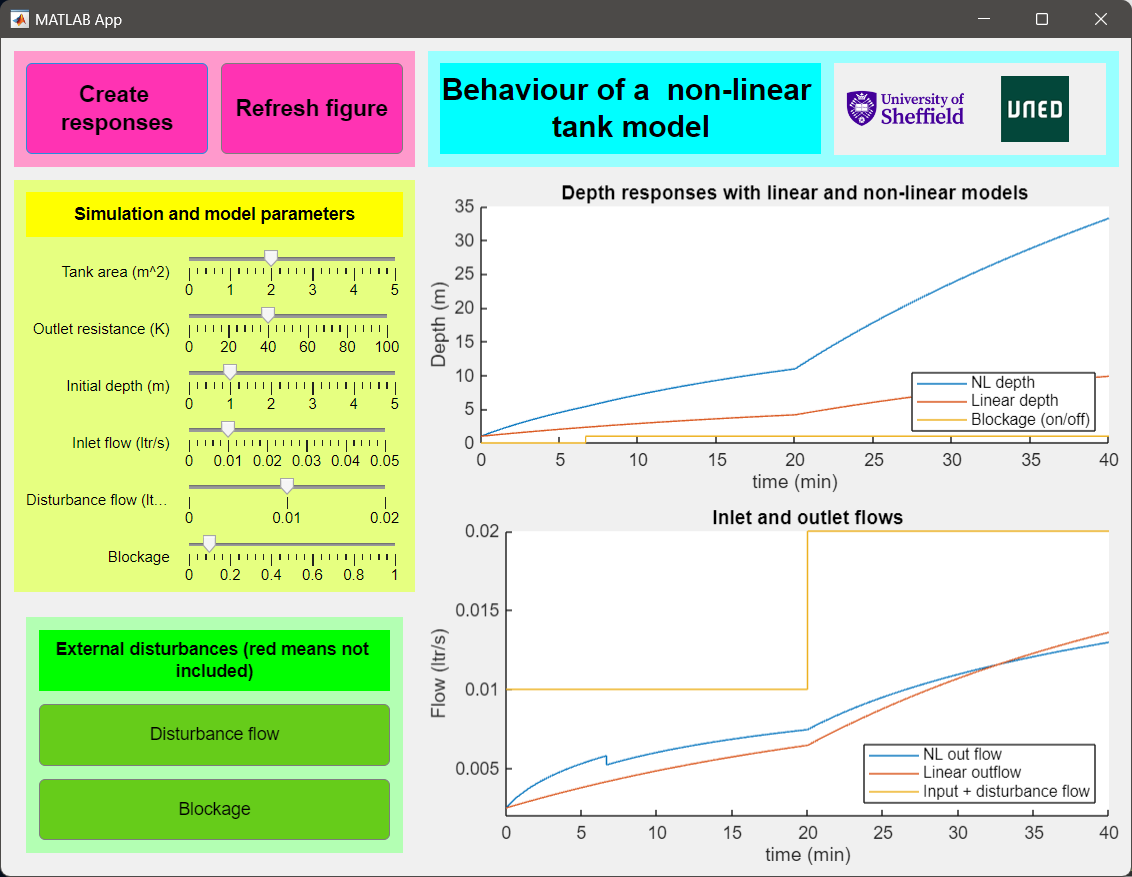

**Figure 3**. Screen dump of the app for illustration (***nonlinear_tank_behaviour_control101.mlapp***)

### ***3.2 App investigating feedback of the non-linear tank model subject to uncertainty and constraints***

This app builds on section 2 above. A core point is to decide what factors a user might wish to change. The app allows the following changes, although only to  a relatively limited degree of precision:

- The magnitude of disturbance in-flow changes but not the timing (can be changed in source file data definitions).

- The magnitude of blockage changes but not the timing (can be changed in source file data definitions).

- The size of the input limits (absolute and rate), but only within set ranges.

- The magnitude of the measurement noise, but only within set ranges.

- The use or not of anti-windup in the PID compensator (the PID values are defined automatically as in section 2.1 so can only be edited in the source code).

These effects can also be turned off entirely using some toggle buttons in the bottom left. It is noted that anti-windup can only deployed if input saturation is activated, so these two buttons cannot always be toggled independently.

The legend will keep track of core values which are not self-evident from a simulation.  A more complete single shot figure for the current simulation is available in one column, and the history in another column.

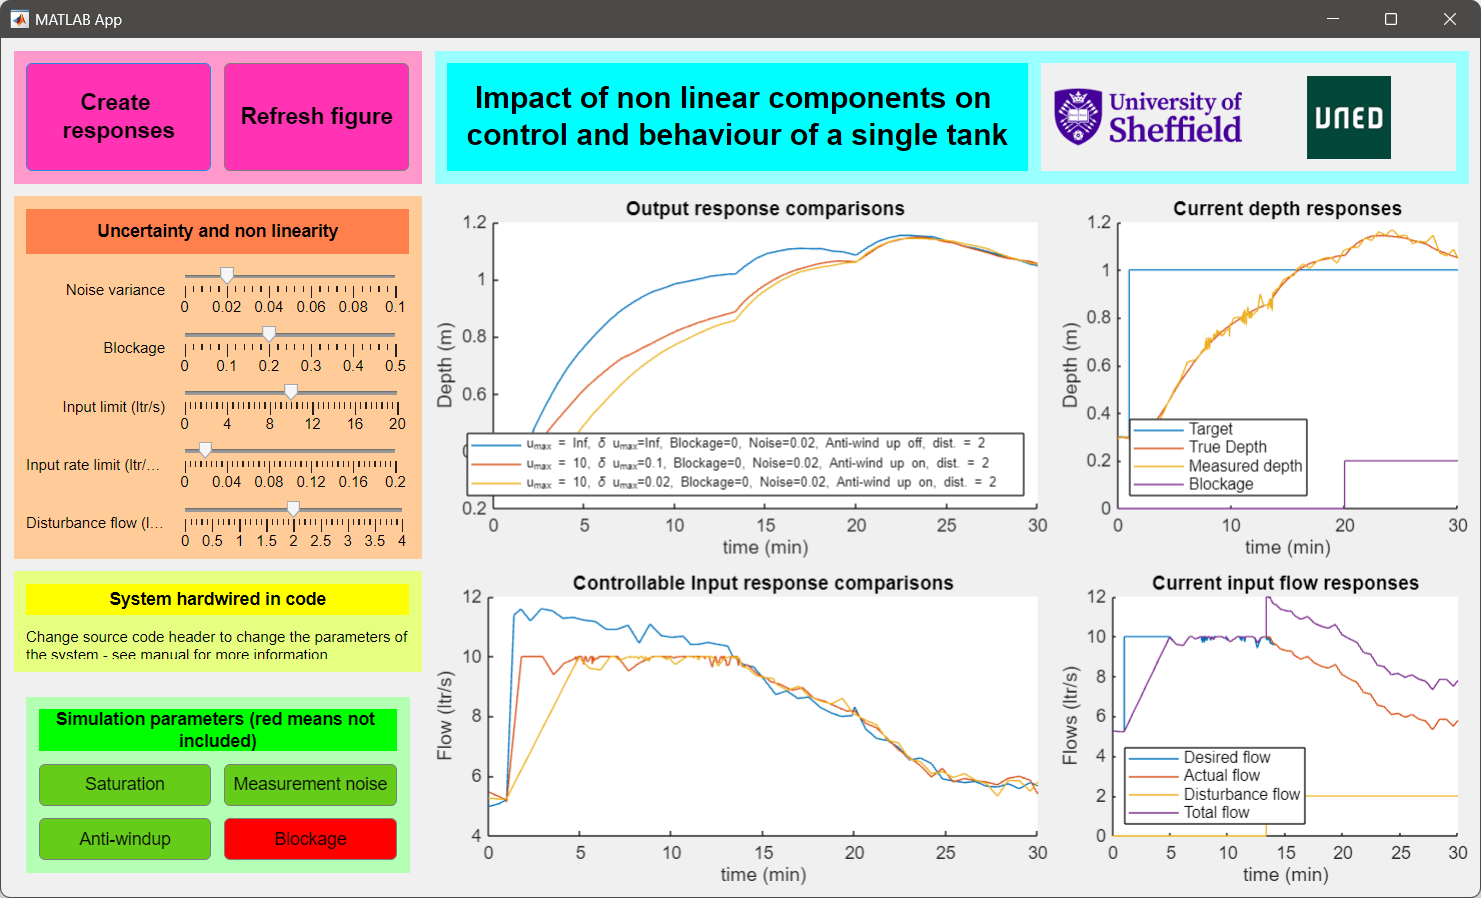

**Figure 4**. Screen dump of the app for illustration (***nonlinear_tank_control_control101.mlapp***)